# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 3.4.8 Backprojection Algorithm - Toyota Avalon

% Speed of light
c = 299792458;

% Set the image span (meters)
x_span = 10;
y_span = 10;

% Number of bins in x and y
nx = 1000;
ny = 1000;

% Set the azimuth span (degrees)
az_start = -0;
az_end = 180;

% Set the window type for the image
window_type = 'Hamming';

% Set the dynamic range of the image
dynamic_range = 40; % dB

% Load the selected target
load('ToyotaAvalon_el30.0000.mat');

% Set the polarization
signal = data.vv;

% Set up the image space
xi = linspace(-0.5 * x_span, 0.5 * x_span, nx);
yi = linspace(-0.5 * y_span, 0.5 * y_span, ny);
[x_image, y_image] = meshgrid(xi, yi);
z_image = zeros(size(x_image));

% Choose the pulses in the azimuth range
sensor_az = [];
index = [];

for i = 1:length(data.azim)
    if az_start <= data.azim(i) && data.azim(i) <= az_end
        sensor_az = [sensor_az, deg2rad(data.azim(i))];
        index = [index, i];
    end
end

% Get the signal for those azimuth angles
signal1 = signal(:, index);

% Get the sensor elevation angles
sensor_el = deg2rad(data.elev) * ones(1, length(sensor_az));

% Get the sensor frequencies
frequency = data.FGHz * 1e9;

% Size of the data
nf = length(frequency);
na = length(sensor_az);

% Set the length of the FFT
fft_length = 4 * 2^nextpow2(length(frequency));

% Get the window coefficients
switch window_type
    case 'Hanning'
        h1 = hanning(nf);
        h2 = hanning(na);
        coefficients = sqrt(h1' * h2);
    case 'Hamming'
        h1 = hamming(nf);
        h2 = hamming(na);
        coefficients = sqrt(h1' * h2);
    case 'None'
        coefficients = ones(nf, na);
end

% Apply the selected window
signal1 = signal1 .* coefficients;

% Reconstruct the image
bp_image = backprojection_cv(signal1, sensor_az, sensor_el, ...
    x_image, y_image, z_image, frequency, fft_length);


#### Plot the focused image

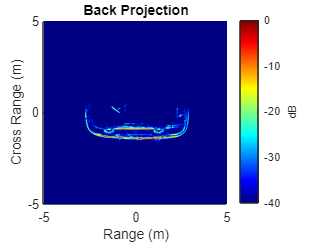

bpi = abs(bp_image) ./ max(max(abs(bp_image)));

figure;
pcolor(xi, yi, 20.0 * log10(bpi)); shading flat;
caxis([-dynamic_range, 0.0])
h = colorbar;
ylabel(h, 'dB');
colormap jet

% Set the plot title and labels
title('Back Projection')
xlabel('Range (m)')
ylabel('Cross Range (m)')
axis('square')